## Changes of coordinates

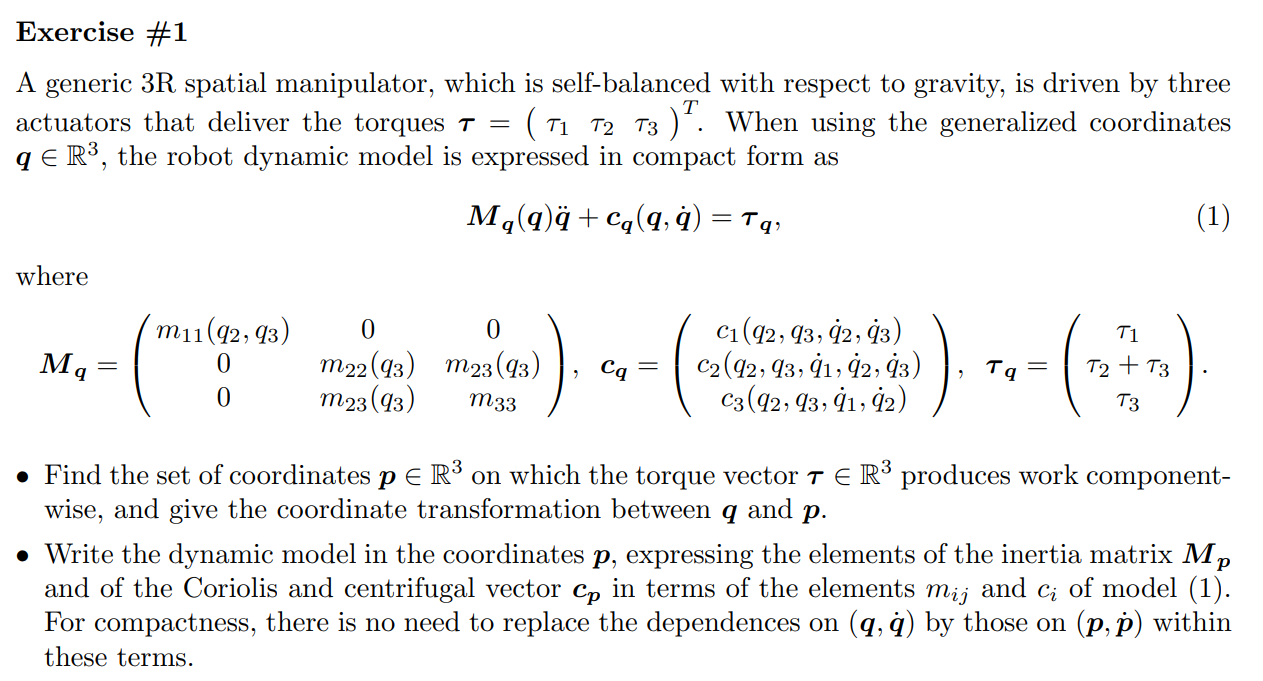

syms tau1 tau2 tau3 m11_q2_q3 m22_q3 m23_q3 m33 c1_q2_q3_dq2_dq3 c2_q2_q3_dq1_dq2_dq3
syms c3_q2_q3_dq1_dq2 p1 p2 p3 dp1 dp2 dp3

M_q = [m11_q2_q3        0        0;
          0          m22_q3    m23_q3;
          0          m23_q3      m33;];
c_q = [c1_q2_q3_dq2_dq3;
       c2_q2_q3_dq1_dq2_dq3;
       c3_q2_q3_dq1_dq2;];

J = [1 0 0;
     0 1 0;
     0 1  1];
J_t = J.';

p = [p1; p2; p3-p2;];
p_dot = [dp1; dp2; dp3-dp2];

tau_q = [tau1; tau2+tau3; tau3];

[M_p, c_p] = coordinate_transformation(M_q,c_q,J,p_dot);

disp("Results: ");

Results: 


disp([M_p, c_p]);

$$\left(\begin{array}{cccc} m_{11,\mathrm{q2},\mathrm{q3}} & 0 & 0 & c_{1,\mathrm{q2},\mathrm{q3},\mathrm{dq2},\mathrm{dq3}}\\ 0 & m_{33}+m_{22,\mathrm{q3}}-2\,m_{23,\mathrm{q3}} & m_{23,\mathrm{q3}}-m_{33} & c_{2,\mathrm{q2},\mathrm{q3},\mathrm{dq1},\mathrm{dq2},\mathrm{dq3}}-c_{3,\mathrm{q2},\mathrm{q3},\mathrm{dq1},\mathrm{dq2}}\\ 0 & m_{23,\mathrm{q3}}-m_{33} & m_{33} & c_{3,\mathrm{q2},\mathrm{q3},\mathrm{dq1},\mathrm{dq2}} \end{array}\right)$$


% Take from Gabbo's git hub

function [M_p, c_p] = coordinate_transformation(M_q, c_q, J,p_dot)
    % M: mass matrix
    % c: coriolis matrix
    % g: gravity matrix
    % tau: torque vector
    % q: joint position vector

    %p = subs(f, q);
    J_inv = inv(J);
    M_p = J_inv' * M_q * J_inv;
    c_p = J_inv' * c_q; % J_inv*p_dot = q_dot? simplify?

end
